# GPH333 Lab 2

Nate Crummett

## Question 1

Distances in AU:

distMars = 1.524;
distEarth = 1;

Kepler's Third Law is P^2 = a^3, where P is period in years and a is distance from the Sun in AU. Thus,

Period = sqrt(distMars^3); % Kepler's Third Law rewritten
PeriodDays = Period*365.25;
disp("There are " + PeriodDays + " Earth days in a Martian Year")

There are 687.1755 Earth days in a Martian Year


## Question 2

#### A)

Insolation is proportional to 1/(r^2). My function inso(x,y) takes this into account. See documentation at the end of this report for details.

[~,insoRel,~,~] = inso(distMars,distEarth);
disp("Mars recieves " + round(insoRel,2,"decimals") + "% insolation less than Earth recieves")

Mars recieves 56.94% insolation less than Earth recieves


#### B)

Eccentricity's are unitless parameters. The closer to zero, the closer to circular. The closer to one, the more stretched the ellipse is.

eEarth = 0.0167;
eMars = 5.6*eEarth; % more elliptical than Earth

As we saw on the board, one can derive an expression for relative insolation in terms of Earth's eccentricity and relative ratios of distance:

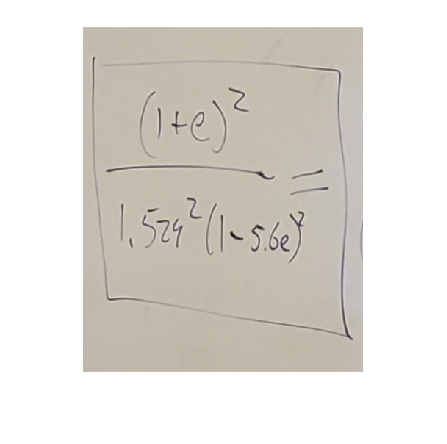

Eqn = imread("Equation.jpg");
grayEqn = im2gray(Eqn);
imshow(Eqn)

I get the same answer using my inso(x,y) function. I use the relations r_perihelion = a*(1-e) and r_aphelion = a*(1+e), the same used to derive the above equation:

r_aphelion_e = distEarth*(1+eEarth);
r_perihelion_m = distMars*(1-eMars);
[insoComp,~,~,~] = inso(r_perihelion_m,r_aphelion_e);
disp("At perihelion, Mars recieves " + round(insoComp,2,"decimals") + ...
    "% of the insolation Earth recieves at its aphelion.")

Mars recieves 54.16% insolation at perihelion relative to Earth at its aphelion


## Question 3

Distance to Venus in AU:

distVenus = 0.723;

Using Kepler's Third Law like in we did in the first question, periods for Earth and Venus are derived:

PeriodV = sqrt(distVenus^3); 
PeriodE = sqrt(distEarth^3);

Now we can use the relative time spent orbiting around the Sun to calculate the insolation per revolution. Using the inso(x,y) function again:

PeriodVE = PeriodV/PeriodE;
[~,~,insoV,insoE] = inso(distVenus,distEarth);
insoVE = insoV/insoE;
insoPerYear = insoVE*PeriodVE*100;
disp("Venus recieves " + round(insoPerYear,2,"decimals") + ...
    "% insolation per revolution relative to Earth.")

Venus recieves 117.61% insolation per revolution relative to Earth.


## Question 4

Reno is at 39 degrees latitude.

Reno = 39;

Summer solstice in the Northern Hemisphere is approximately at aphelion. And winter solstice is approximately at the perihelion of Earth's orbit. Different times of year mean the same place on Earth will be at different places relative to the ecliptic. So, multiply  insolation values by a function of latitiude, cos(latitide +- 23.5). Here, 23.5 is the tilt of Earth's axis in degrees from the ecliptic.

summer = cosd(Reno - 23.5);
winter = cosd(Reno + 23.5);
r_perihelion_e = distEarth*(1-eEarth);
[~,~,insoRenoAph,insoRenoPer] = inso(r_aphelion_e,r_perihelion_e);
insoSummer = summer*insoRenoAph;
insoWinter = winter*insoRenoPer;
winSum = (insoSummer-insoWinter)/insoSummer*100;
disp("The winter solstice recieves " + round(winSum,2,"decimals") +...
    "% less insulation than summer solstice in Reno Nevada.")

The winter solstice recieves 48.77% less insulation than summer solstice in Reno Nevada.


## Question 5

What was shown in class:

vAvg = 29.78; % km/s
timeAvg = 3.9425; % minutes longer than siderial day

Because of eccentricity, Earth's velocity is different at different times of the year.

vJan = 30.287; % km/s
vJuly = 29.291; % km/s

Comparing velocities does not make sense here, because amount of area 'swept out' by the planet is a function of angular velocity. To account for this, we need distances at each time of year. January 3rd is close to perihelion. As is July 4th to aphelion. This allows us to make a more accurate calculation.

omegaJan = vJan/r_perihelion_e;
omegaJuly = vJuly/r_aphelion_e;
omegaAvg = vAvg/distEarth;

Now using the average as a middle man, we can set up a ratio and solve for January and July times seperately.

timeJan = omegaJan*timeAvg/omegaAvg;
timeJuly = omegaJuly*timeAvg/omegaAvg;
diff = (timeJan-timeJuly)*60; % seconds
disp("January 1st is " + round(diff,2,"decimals") + ...
    " seconds longer than July 4th.")

January 1st is 15.82 seconds longer than July 4th.


## Question 6

We are given a few pieces of information:

denFe = 8000; %kg/m^3
mEarth = 5.96E24; %kg
distmEarth = distEarth*1.496E11; %m
radiusmEarth = 6371000; %m
vMeteor = 30000; %m/s

This is a conservation of angular momentum problem. So the angular momentum of Earth (orbiting around the Sun) must be equal and opposite to the momentum of meteor (colliding with Earth). Earth is not spinning, so angular momentum is due only to its orbit around the Sun.

IEarth = mEarth*distmEarth^2; %kg*m^2
omega = 2*pi/(365.25*24*60*60); %rad/sec
LEarth = IEarth*omega;

The meteor has angular momentum LMeteor = mMeteor*vMeteor*rMeteor. We can set this equal to LEarth, beause they need to be equal. Thus we can solve for mMeteor.

rMeteor = distmEarth;
mMeteor = LEarth/(vMeteor*rMeteor);
massComp = mMeteor/mEarth*100;
disp("The meteor needs to have a mass of " + ...
    round(mMeteor,3,"significant") + " kg. That is " +...
    round(massComp,2,"decimals") + "% of Earth's mass.")

The meteor needs to have a mass of 5.92e+24 kg. That is 99.29% of Earth's mass.


If you are having trouble understanding my code, I double checked my work with paper and pencil (pen):

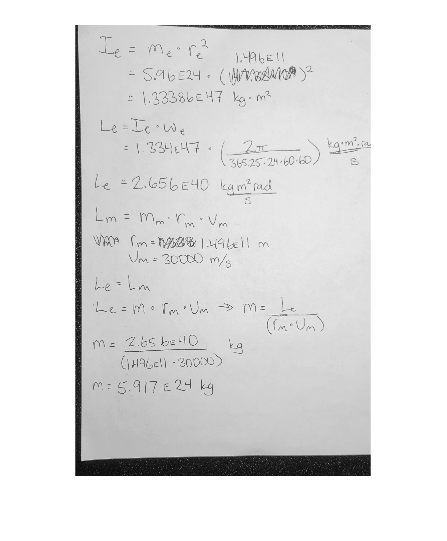

workEqn = imread("Work.jpg");
workEqn = im2gray(workEqn);
imshow(workEqn)

Assuming the meteor is a sphere, and made of solid iron, we can solve for it's size.

radiusmMeteor = (3*mMeteor/(4*pi*denFe))^(1/3);
radComp = radiusmMeteor/radiusmEarth*100;
disp("The meteor's radius is " + round(radComp,2,"decimals") + "% of Earth's"+...
    " radius.")

The meteor's radius is 88.06% of Earth's radius. This makes sense, because on average Earth is less dense than solid iron.


disp("Thus on average, Earth is less dense than solid iron.")

That is kind of nuts... but it also makes sense... Like, to stop Earth from orbiting the Sun, just run an astroid with nearly identical mass and velocity into Earth in the opposite direction. 

## Extra Credit

The time's between the autumnal and vernal equinox are given respectively below:

SeptMarch = 179; %days
MarchSept = 186; %days
year = SeptMarch + MarchSept;

I am going to use Kepler's First Law - the units do not matter to me because everything is going to go relative here in a second. I am assuming for each case Earth has an eccentricity of zero and will compare them when I am done

P1 = SeptMarch*2/year;
P2 = MarchSept*2/year;
dist1 = (P1^2)^(1/3);

dist1 = 0.9872

dist2 = (P2^2)^(1/3);

dist2 = 1.0127

Since eccentricity can be related to distance by r = a*(1+-e), we can solve for e. Here, a is the same for both in the real world. And since I assumed e=0 above, r is the distances for each. For small eccentricities, I derived an equation with the relationship:

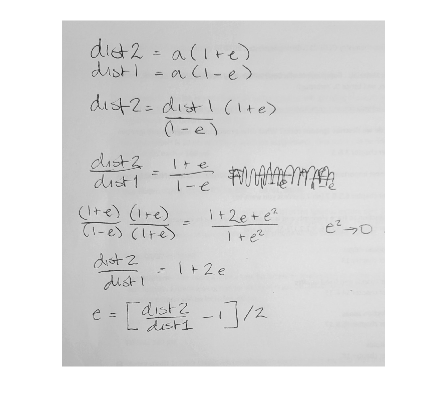

derive = imread("20220130_131755.jpg");
derive = im2gray(derive);
imshow(derive)

eApprox = ((dist2/dist1)-1)/2;
relE = (eEarth-eApprox)/eEarth*100;
disp("My approximation is for e is " + round(eApprox,3,"significant") + ...
    ". Relative to Earth's e, this is " + round(relE,2,"decimals") + "% less.")

My approximation is for e is 0.013. Relative to Earth's e, this is 22.44% less.


## Functions

The insolation function. This calculates 

function [insoComp,insoRel,inso,inso2] = inso(dist,dist2)
    inso = 1/dist^2;
    inso2 = 1/dist2^2;
    insoComp = inso/inso2*100;
    insoRel = (inso2-inso)/inso2 *100;
end